## Lab 3 Step 1 Starter Code

clear all;
close all;
clc;
% load csv data. Put data into column vectors.
% convert from degrees to radians
M = readmatrix("mocap_data.csv");

% Number of rows in M = Number of samples from motion capture system
N = size(M,1);

t = M(:,1);
x = M(:,2);
y = M(:,3);
z = M(:,4);

p = [x y z]; % position vector (in m)

roll = deg2rad(M(:,5));
pitch = deg2rad(M(:,6));
yaw = deg2rad(M(:,7));

**Problem 1a**

For this problem, you need to use `subplot.`

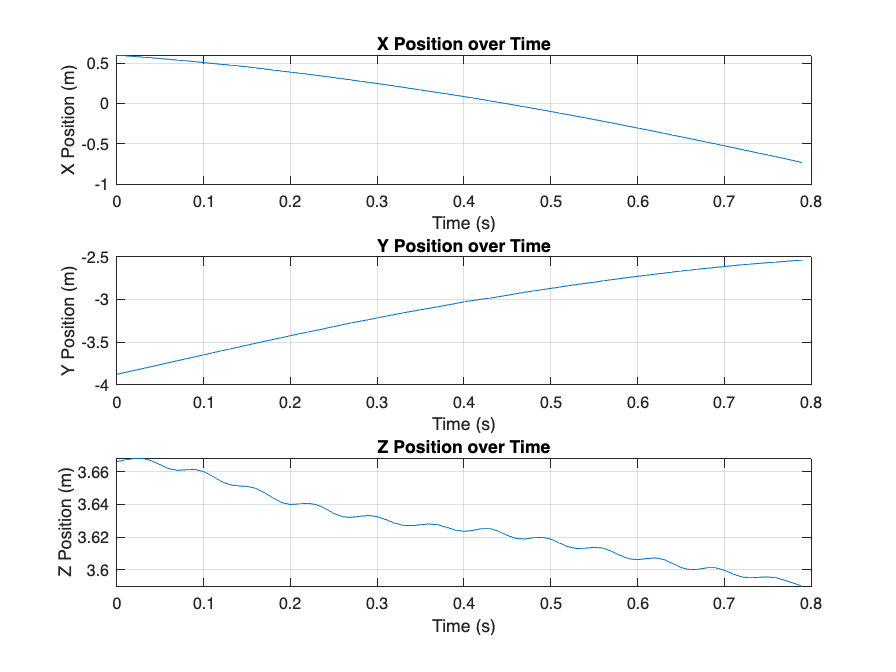

% X
figure
subplot(3, 1, 1);
plot(t, x);
title('X Position over Time');
xlabel('Time (s)');
ylabel('X Position (m)');
grid on; 

% Y 
subplot(3, 1, 2);
plot(t, y);
title('Y Position over Time');
xlabel('Time (s)');
ylabel('Y Position (m)');
grid on;

% Z
subplot(3, 1, 3); 
plot(t, z);
title('Z Position over Time');
xlabel('Time (s)');
ylabel('Z Position (m)');
grid on;
saveas(gcf, 'position_plot.png'); 

**Problem 1b**

We approximate the velocities using the definition of a derivative, and replacing $h$ with $\Delta t$.


$$v(t) = \lim_{h \rightarrow 0^+} \frac{p(t+h)-p(t)}{h} \Rightarrow
v(t_i) \approx  \frac{p(t_{i+1})-p(t_i)}{t_{i+1}-t_i} $$


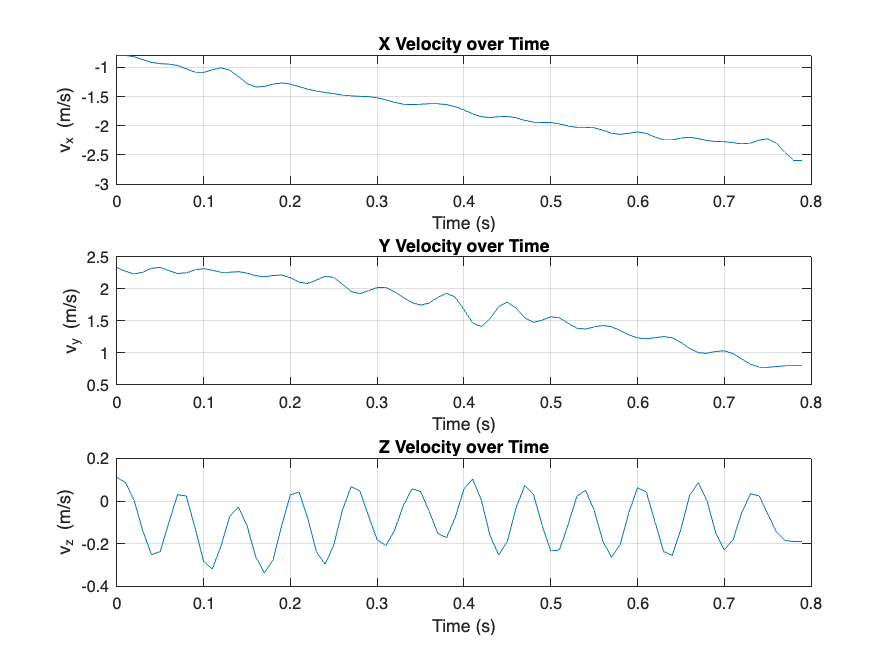

% Calculate velocities numerically
v = zeros(N,3);

%Pos matrix
p = [x, y, z];
%differneces in time steps
dp = diff(p); 
dt = diff(t);

% 1. dervi
v_temp = dp ./ dt;

%expand vector
v = [v_temp; v_temp(end, :)];
%v(end,:) = v(end-1,:);

% plot the figure
figure
subplot(3, 1, 1);
plot(t, v(:, 1)); 
title('X Velocity over Time');
xlabel('Time (s)');
ylabel('v_x (m/s)');
grid on;

subplot(3, 1, 2);
plot(t, v(:, 2)); 
title('Y Velocity over Time');
xlabel('Time (s)');
ylabel('v_y (m/s)');
grid on;

subplot(3, 1, 3);
plot(t, v(:, 3)); 
title('Z Velocity over Time');
xlabel('Time (s)');
ylabel('v_z (m/s)');
grid on;
saveas(gcf, 'vell_plot.png');

**Problem 1c**

First we need to convert roll-pitch-yaw to rotation matrices. You can either use change of basis (MLS p. 31-33) or use the `eul2rotm` function from the Robotics Toolbox to do the job. (This part is done for you.)

% convert rpy to rotation matrices by hand (MLS p. 31-33)
R = zeros(3,3,N);

% using inline functions to make our code easier to read
Rx = @(phi) [1 0 0; 0 cos(phi) -sin(phi); 0 sin(phi) cos(phi)];
Ry = @(beta) [cos(beta) 0 sin(beta); 0 1 0; -sin(beta) 0 cos(beta)];
Rz = @(alpha) [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1];

for i=1:N
    R(:,:,i) = Rz(yaw(i))*Ry(pitch(i))*Rx(roll(i));
end

% convert rpy to rotation matrices using Robotics Toolbox
% this code works identically to above!
% eul = [yaw pitch roll];
% Rotm = eul2rotm(eul,'ZYX');

Now implement ECE569_MatrixLog3, ECE569_so3ToVec, ECE569_VecToso3, ECE569_AxisAng3 in their respective .m files. When you have written them, run the command "runtests" in the Command Window.

Once you have done that, take a matrix logarithm to obtain $$\widehat{\omega} \theta$ (the exponential coordinate of $R=e^{\widehat{\omega}\theta}$)$. Then, perform manipulations to obtain $\hat \omega$ and $\theta$ where $\omega$ is a unit vector representing the axis of rotation.

% get (w,theta) from e^(w_hat_theta)
w = zeros(N,3);
theta = zeros(N,1);
for i=1:N
    Ri = R(:,:,i);

    w_hat_theta = ECE569_MatrixLog3(Ri);
    w_theta = ECE569_so3ToVec(w_hat_theta);
    [w(i,:),theta(i)] = ECE569_AxisAng3(w_theta);

    % Calculate the matrix logarithm as we learned in class
    % See MR textbook eqn. 3.58
    
    % you will need to assign values to w(i,:) and theta(i)

end

Finally, plot the desired signals with appropriate labels.

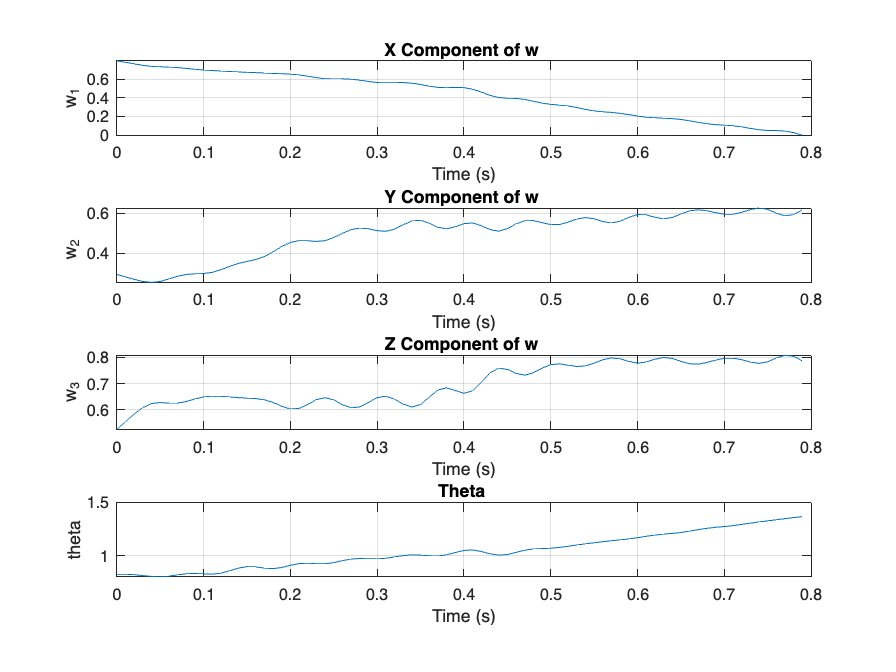

figure;

subplot(4, 1, 1);
plot(t, w(:, 1)); 
title('X Component of w ');
xlabel('Time (s)');
ylabel('w_1');
grid on;


subplot(4, 1, 2);
plot(t, w(:, 2)); 
title('Y Component of w ');
xlabel('Time (s)');
ylabel('w_2 ');
grid on;


subplot(4, 1, 3);
plot(t, w(:, 3)); 
title('Z Component of w ');
xlabel('Time (s)');
ylabel('w_3');
grid on;

subplot(4, 1, 4);
plot(t, theta); 
title('Theta ');
xlabel('Time (s)');
ylabel('theta');
grid on;

% Save the final plot as a PNG image
saveas(gcf, 'roll-pitch-yaw.png');

**Problem 1d**

Take a matrix logarithm of $R(t_i)^\top R(t_{i+1})$ and then do manipulations to obtain $\omega^b(t_i)$, which we defined as $\omega^b(t_i)=\frac{\omega(t_i)\theta(t_i)}{t_{i+1}-t_i}$.

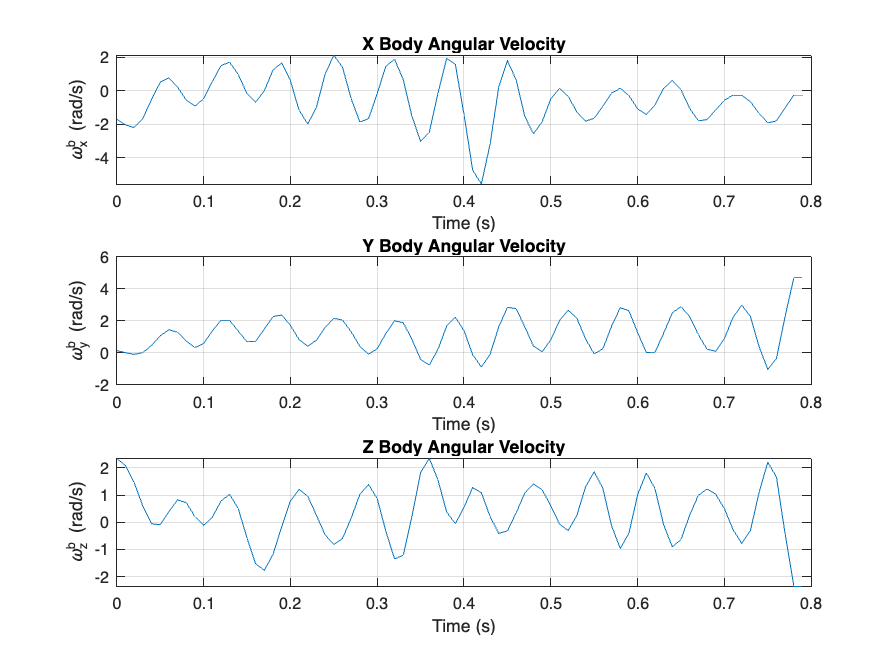

% Calculate angular velocity

omega_b_temp = zeros(N-1, 3);

for i = 1:(N-1)
    
    R_i = R(:, :, i);
    R_i_next = R(:, :, i+1);

    R_inc = R_i' * R_i_next;

    w_hat_theta = ECE569_MatrixLog3(R_inc);

    w_theta = ECE569_so3ToVec(w_hat_theta);
    
    omega_b_temp(i, :) = w_theta / (t(i+1) - t(i));
end

% fill last point 
omega_b = zeros(N, 3);
omega_b(1:N-1, :) = omega_b_temp;
omega_b(N, :) = omega_b(N-1, :);



figure;
subplot(3, 1, 1);
plot(t, omega_b(:, 1)); 
title('X Body Angular Velocity');
xlabel('Time (s)');
ylabel('\omega^b_x (rad/s)');
grid on;

subplot(3, 1, 2);
plot(t, omega_b(:, 2)); 
title('Y Body Angular Velocity');
xlabel('Time (s)');
ylabel('\omega^b_y (rad/s)');
grid on;

subplot(3, 1, 3);
plot(t, omega_b(:, 3)); 
title('Z Body Angular Velocity');
xlabel('Time (s)');
ylabel('\omega^b_z (rad/s)');
grid on;


saveas(gcf, 'body_angular_velocity.png');

**Problem 1e**

Plot the function $d(R(t),R_d)^2 = 2Tr(I-R^\top R_d)$ 

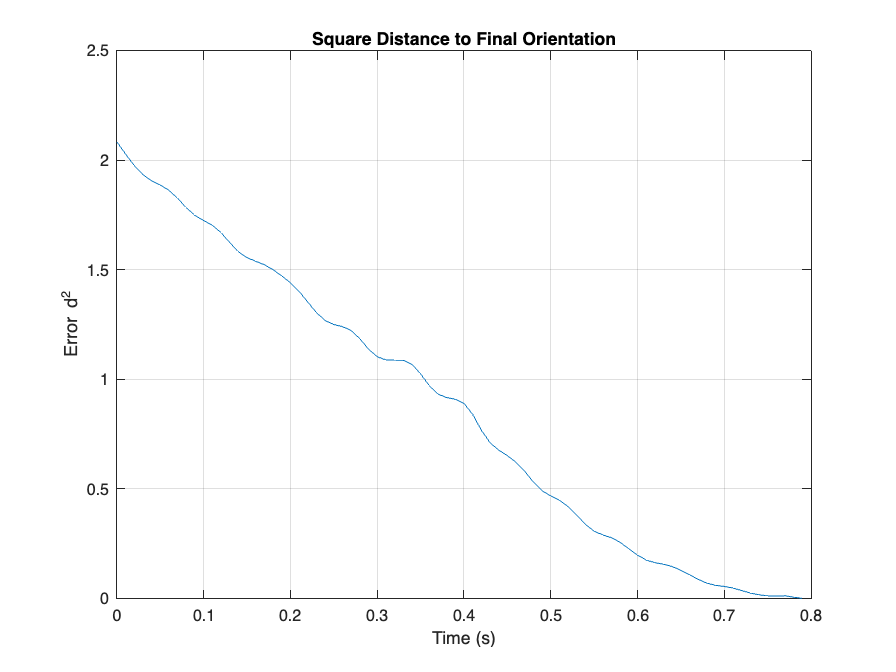

% calc d^2
N = size(R, 3);
Rd = R(:, :, N); 

d = zeros(N, 1);

for i = 1:N

    Ri = R(:, :, i);
    d(i) = 2*trace(eye(3) - Rd'*Ri);
    
end

figure;

plot(t, d)
title('Square Distance to Final Orientation');


xlabel('Time (s)');
ylabel('Error d^2');
grid on;
saveas(gcf, 'rotation_error_plot.png')